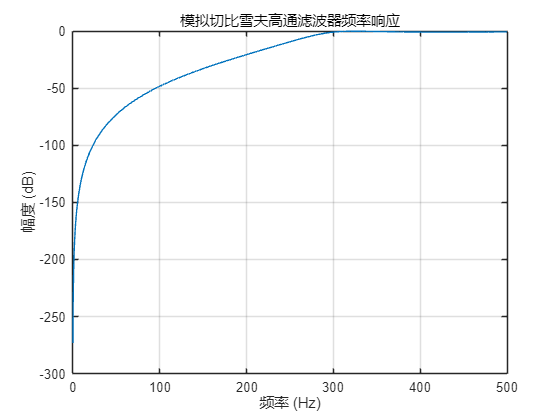

clc;
clear;
fc=300;
fr=200;
T=0.001;
fs=1/T;
Rp=0.8;
Rs=20;
wc=2*pi*fc;
wr=2*pi*fr;
omega=0:1000*pi;
[N,Wn]=cheb1ord(wc,wr,Rp,Rs,'s'); 
[B,A]=cheby1(N,Rp,Wn,'high','s'); 
h=freqs(B,A,omega);
h_abs=20*log10(abs(h));
figure;
plot(omega/(2*pi), h_abs);
xlabel('频率 (Hz)');
ylabel('幅度 (dB)');
title('模拟切比雪夫高通滤波器频率响应');
grid on;

%%脉冲响应不变法

clc;
clear;
fc=200;
fr=300;
T=0.001;
fs=1/T;
Rp=1;
Rs=25;
wc=2*pi*fc;
wr=2*pi*fr;
[N,Wn]=buttord(wc,wr,Rp,Rs,'s'); 
[B,A]=butter(N,Wn,'low','s'); 
[num1,den1]=impinvar(B,A,fs);
[h1,w]=freqz(num1,den1);
f=w/(2*pi)*fs;
figure;
plot(f,20*log10(abs(h1)),'b-');hold on
%双线性变换法
wc=2/T*tan(2*pi*fc*T/2);
wr=2/T*tan(2*pi*fr*T/2);
[N,Wn]=buttord(wc,wr,Rp,Rs,'s'); 
[B,A]=butter(N,Wn,'low','s'); 
[num2,den2]=bilinear(B,A,fs);

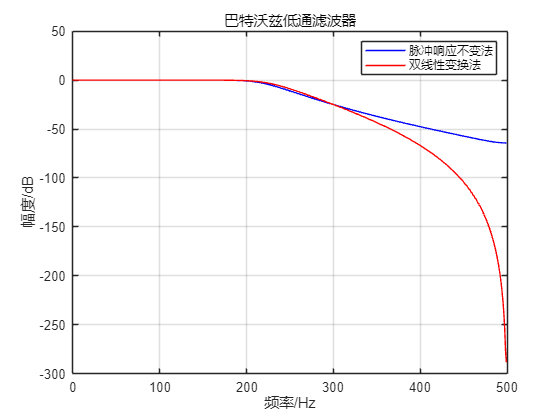

[h2,w2]=freqz(num2,den2);
f2=w2/(2*pi)*fs;
plot(f2,20*log10(abs(h2)),'r-');grid on;
legend('脉冲响应不变法','双线性变换法');
xlabel('频率/Hz');
ylabel('幅度/dB');
title('巴特沃兹低通滤波器');

clc;
clear;
fc=1200;
fr=2000;

fs=8000;
T=1/fs;
Rp=0.5;
Rs=40;
wc=2/T*tan(2*pi*fc*T/2);
wr=2/T*tan(2*pi*fr*T/2);
%%巴特沃斯
[N1,W1]=buttord(wc,wr,Rp,Rs,'s'); 
N1

N1 = 9


[B,A]=butter(N1,W1,'low','s'); 
[num1,den1]=bilinear(B,A,fs);

[h1,w1]=freqz(num1,den1);
f1=w1/(2*pi)*fs;
figure;
plot(f1,20*log10(abs(h1)),'r-');hold on;
%%切比雪夫
[N2,W2]=cheb1ord(wc,wr,Rp,Rs,'s'); 
N2

N2 = 5

[B,A]=cheby1(N2,Rp,W2,'low','s'); 
[num2,den2]=bilinear(B,A,fs);

[h2,w2]=freqz(num2,den2);
f2=w2/(2*pi)*fs;
plot(f2,20*log10(abs(h2)),'b--');grid on;

wc=2/T*tan(2*pi*fc*T/2);
wr=2/T*tan(2*pi*fr*T/2);
[N3,W3]=ellipord(wc,wr,Rp,Rs,'s');
N3

N3 = 4

[B,A]=ellip(N3,Rp,Rs,W3,'s');
[num3,den3]=bilinear(B,A,fs);

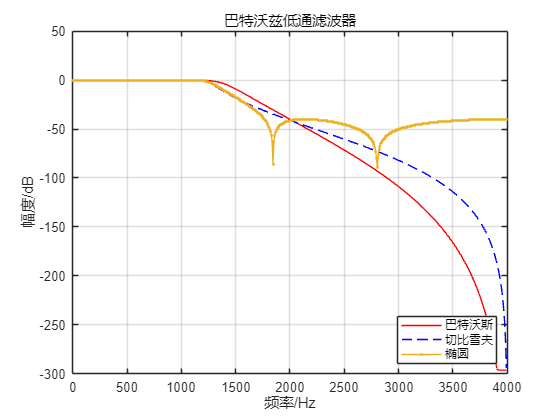

[h3,w3]=freqz(num3,den3);
f3=w3/(2*pi)*fs;
plot(f3,20*log10(abs(h3)),'.-');grid on;
xlabel('频率/Hz');
ylabel('幅度/dB');
legend('巴特沃斯','切比雪夫','椭圆',Location='southeast');
title('巴特沃兹低通滤波器');

%%脉冲响应不变法

clc;
clear;
fc1=2000;
fc2=3000;
fr1=1500;
fr2=6000;
fs=3e4;
T=1/fs;
Rp=3;
Rs=20;
w1=2*pi*fc1;
w2=2*pi*fc2;
wr1=2*pi*fr1;
wr2=2*pi*fr2;
[N,Wn]=buttord([w1 w2],[wr1 wr2],Rp,Rs,'s'); 
[B,A]=butter(N,Wn,'s'); 
[num1,den1]=impinvar(B,A,fs);
[h1,w]=freqz(num1,den1);
f=w/(2*pi)*fs;
figure;
plot(f,20*log10(abs(h1)),'b-');hold on;
%%双线性变换法

clc;
clear;
fc1=2000;
fc2=3000;
fr1=1500;
fr2=6000;
fs=3e4;
T=1/fs;
Rp=3;
Rs=20;
w1=2/T*tan(2*pi*fc1*T/2);
w2=2/T*tan(2*pi*fc2*T/2);
wr1=2/T*tan(2*pi*fr1*T/2);
wr2=2/T*tan(2*pi*fr2*T/2);
[N,Wn]=buttord([w1 w2],[wr1 wr2],Rp,Rs,'s'); 
[B,A]=butter(N,Wn,'s'); 
[num1,den1]=bilinear(B,A,fs);

[h1,w]=freqz(num1,den1);
f=w/(2*pi)*fs;
plot(f,20*log10(abs(h1)),'r-');grid on;
legend('脉冲响应不变法','双线性变换法');
xlabel('频率/Hz');
ylabel('幅度/dB');
title('巴特沃兹带通滤波器');
 
xLine = findobj(gcf, "DisplayName", "双线性变换法")

xLine =   Line (双线性变换法) - 属性:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 29.2969 58.5938 87.8906 117.1875 146.4844 175.7812 205.0781 234.3750 263.6719 292.9687 322.2656 351.5625 380.8594 410.1562 439.4531 468.7500 498.0469 527.3437 556.6406 585.9375 615.2344 644.5313 673.8281 … ] (1×512 double)
              YData: [-264.8355 -134.4853 -116.4126 -105.8289 -98.3071 -92.4597 -87.6687 -83.6044 -80.0699 -76.9383 -74.1229 -71.5618 -69.2093 -67.0306 -64.9988 -63.0923 -61.2939 -59.5893 -57.9668 -56.4165 -54.9299 -53.4999 -52.1202 … ] (1×512 double)

  显示 所有属性


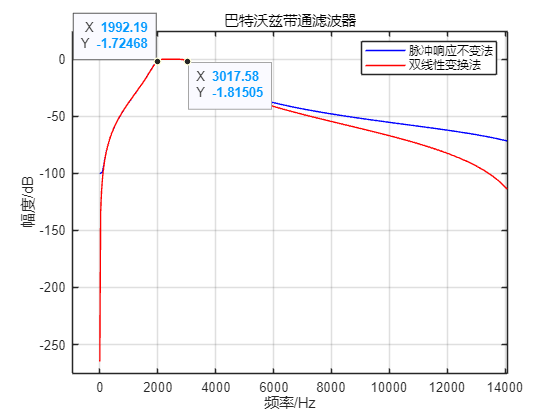

datatip(xLine,3018,-1.815);
datatip(xLine,1992,-1.725,"Location","northwest");

clc;
clear;
fc1=1000;
fc2=2000;
fr1=500;
fr2=3000;
fs=10000;
T=1/fs;
Rp=18;
Rs=3;
w1=2/T*tan(2*pi*fc1*T/2);
w2=2/T*tan(2*pi*fc2*T/2);
wr1=2/T*tan(2*pi*fr1*T/2);
wr2=2/T*tan(2*pi*fr2*T/2);
[N,Wn]=buttord([wr1 wr2],[w1 w2],Rs,Rp,'s'); 
[B,A]=butter(N,Wn,'stop','s'); 
[num1,den1]=bilinear(B,A,fs);

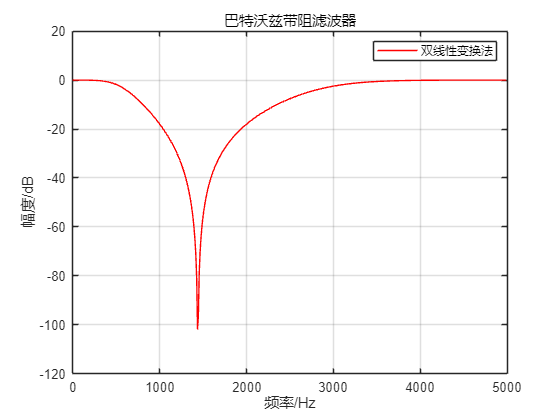

[h1,w]=freqz(num1,den1);
f=w/(2*pi)*fs;
figure;
plot(f,20*log10(abs(h1)),'r-');grid on;
legend('双线性变换法');
xlabel('频率/Hz');
ylabel('幅度/dB');
title('巴特沃兹带阻滤波器');